# Project 1

# Design of Machinery 

# Hana Shamsaei 

Student ID : 810600097

## Defining known parameters

clear,clc,close all

syms theta_3 theta_4 theta_5 theta_6 theta_7 theta_8
syms omega_3 omega_4 omega_5 omega_6 omega_7 omega_8
syms alpha_3 alpha_4 alpha_5 alpha_6 alpha_7 alpha_8 T_1

F_12 = sym("F12", [2,1]);
F_32 = sym("F32", [2,1]);
F_43 = sym("F43", [2,1]);
F_54 = sym("F54", [2,1]);
F_14 = sym("F14", [2,1]);
F_65 = sym("F65", [2,1]);
F_16 = sym("F16", [2,1]);
 
% Lengths of links (m)
r_1 = 98e-2; 
r_2 = 49e-2;
r_3 = 145e-2;
r_4 = 121e-2;
r_5 = 97e-2;
r_6 = 145e-2;
r_7 = 85e-2;
r_8 = 55e-2;
r_9 = 182e-2;

% Lengths of triangle heads to center of mass 
r_34 = 568.09822071e-3; 
r_14 = 765.6474052e-3;
r_54 = 311.04540938e-3;

theta_1 = 0;  % ground
theta_2 = deg2rad(143);  % input
theta_9 = 0;  % gorund

% Angles between side and median of link 4 (for analysis)
theta_34 = deg2rad(12.20286392);
theta_54 = deg2rad(84.23135997);
theta_14 = deg2rad(11.69962314);

omega_1 = 0;  % ground
omega_2 = 1;  % input
omega_9 = 0;  % ground

alpha_1 = 0;  % ground
alpha_2 = 0;  % input
alpha_9 = 0;  % ground

rho_linear = 1;  % Linear density (kg/m)
rho_surface = 1;  % Surface density (kg/m^2)

A_4 = 236842.80e-6;  % Area of link 4 (the triangle)

% Calculating masses of links (kg)
m_2 = r_2 * rho_linear;
m_3 = r_3 * rho_linear;
m_4 = A_4 * rho_surface;
m_5 = r_5 * rho_linear;
m_6 = r_6 * rho_linear;

% I_zz of links (kg.m^2)
I_2 = 9.56298585E-06;
I_3 = 2.521022934E-04;
I_4 = 1.984928192E-05;
I_5 = 1.273390233E-04;
I_6 = 2.582011494E-04;

g = 9.81;  % gravity
P = 200;
T= 20;

t_last = 10;  % Run time
n = 116; % number of loop

## Posture Analysis

theta2(1) = theta_2;

% loop 1

eq(1) = real( r_2*exp(1i*((theta2(1)))) + r_3*exp(1i*((theta_3)))...
    + r_4*exp(1i*((theta_4))) ) == real( r_1*exp(1i*((theta_1))) );
eq(2) = imag( r_2*exp(1i*((theta2(1)))) + r_3*exp(1i*((theta_3)))...
    + r_4*exp(1i*((theta_4))) ) == ...
    imag( r_1*exp(1i*((theta_1))) );

[theta3(1) theta4(1)] = vpasolve([eq(1) eq(2)] , [theta_3 theta_4] , ...
    [deg2rad(43), deg2rad(282)]);

% loop 2

eq(3) = real( r_4*exp(1i*((theta4(1)))) + r_7*exp(1i*((theta_7))) ) ==...
    real( r_8*exp(1i*((theta_8))) );
eq(4) = imag( r_4*exp(1i*((theta4(1)))) + r_7*exp(1i*((theta_7))) ) ==...
    imag( r_8*exp(1i*((theta_8))) );

[theta7(1) theta8(1)] = vpasolve([eq(3) eq(4)] , [theta_7 theta_8]...
    , [deg2rad(82)  , deg2rad(328)]);

% loop 3

eq(5) = real( r_7*exp(1i*((theta7(1)))) + r_5*exp(1i*((theta_5))) ) ==...
    real( r_6*exp(1i*((theta_6))) + r_9*exp(1i*((theta_9))) );
eq(6) = imag( r_7*exp(1i*((theta7(1)))) + r_5*exp(1i*((theta_5))) ) ==...
    imag( r_6*exp(1i*((theta_6))) + r_9*exp(1i*((theta_9))) );

[theta5(1) theta6(1)] = vpasolve([eq(5) eq(6)] , [theta_5 theta_6] , ...
    [deg2rad(16)  , deg2rad(114)]);

% other loops
k = 1;
for j = 0 : 1 : n-2
   
    theta2(k+1) = theta2(k) + 5*pi/180;

    k = k + 1;

    eq(1) = real( r_2*exp(1i*((theta2(k)))) + r_3*exp(1i*((theta_3)))...
        + r_4*exp(1i*((theta_4))) ) == real( r_1*exp(1i*((theta_1))) );
    eq(2) = imag( r_2*exp(1i*((theta2(k)))) + r_3*exp(1i*((theta_3)))...
        + r_4*exp(1i*((theta_4))) ) == imag( r_1*exp(1i*((theta_1))) );
   
    [theta3(k), theta4(k)] = vpasolve([eq(1) eq(2)] , [theta_3 theta_4] ,...
        [deg2rad(43), deg2rad(282)]);
   
    % loop 2
   
    eq(3) = real( r_4*exp(1i*((theta4(k)))) + r_7*exp(1i*((theta_7))) )...
        == real( r_8*exp(1i*((theta_8))) );
    eq(4) = imag( r_4*exp(1i*((theta4(k)))) + r_7*exp(1i*((theta_7))) )...
        == imag( r_8*exp(1i*((theta_8))) );
   
    [theta7(k) theta8(k)] = vpasolve([eq(3) eq(4)] , [theta_7 theta_8] ,...
        [deg2rad(82)  , deg2rad(328)]);
   
    % loop 3
   
    eq(5) = real( r_7*exp(1i*((theta7(k)))) + r_5*exp(1i*((theta_5))) ) ==...
        real( r_6*exp(1i*((theta_6))) + r_9*exp(1i*((theta_9))) );
    eq(6) = imag( r_7*exp(1i*((theta7(k)))) + r_5*exp(1i*((theta_5))) ) ==...
        imag( r_6*exp(1i*((theta_6))) + r_9*exp(1i*((theta_9))) );
   
    [theta5(k) theta6(k)] = vpasolve([eq(5) eq(6)] , [theta_5 theta_6] , ...
        [deg2rad(16)  , deg2rad(114)]);

   
end

## Ploting Posture Analysis

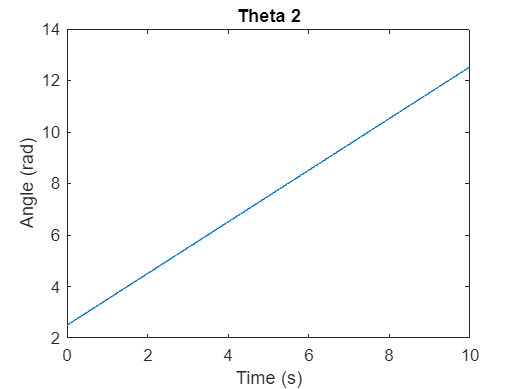

t = 0 : t_last/(n-1) : t_last;
plot(t,theta2)
title('Theta 2')
xlabel('Time (s)')
ylabel('Angle (rad)')

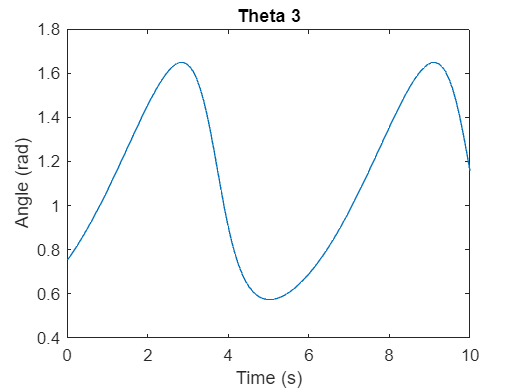


plot(t,theta3)
title('Theta 3')
xlabel('Time (s)')
ylabel('Angle (rad)')

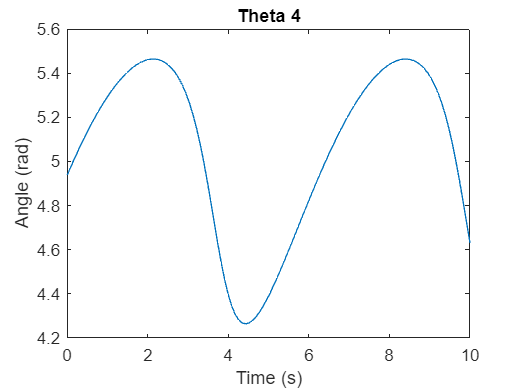


plot(t,theta4)
title('Theta 4')
xlabel('Time (s)')
ylabel('Angle (rad)')

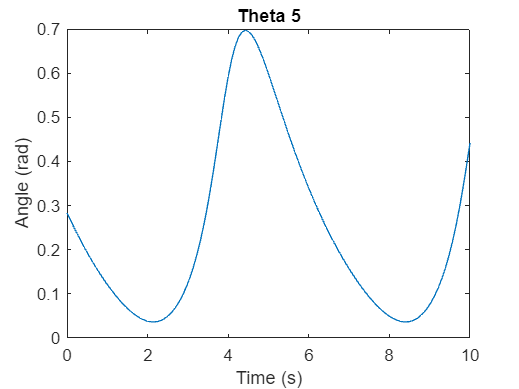


plot(t,theta5)
title('Theta 5')
xlabel('Time (s)')
ylabel('Angle (rad)') 

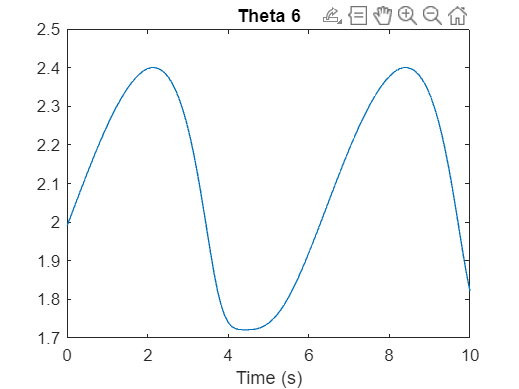


plot(t,theta6)
title('Theta 6')
xlabel('Time (s)')

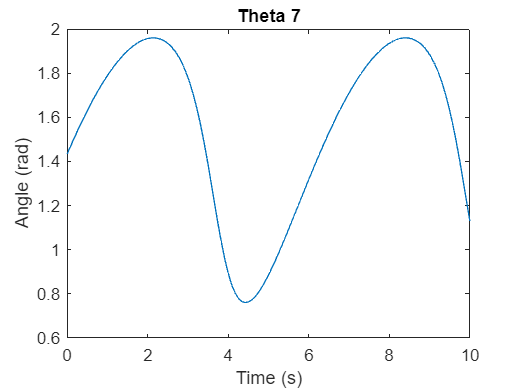


plot(t,theta7)
title('Theta 7')
xlabel('Time (s)')
ylabel('Angle (rad)')

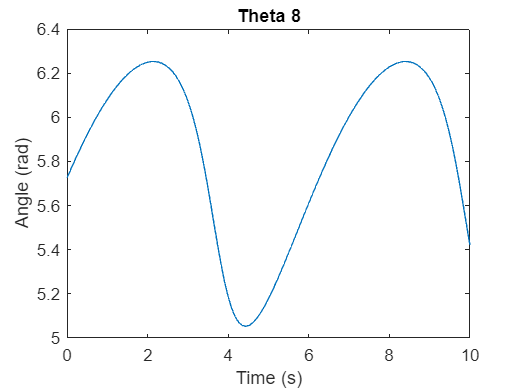


plot(t,theta8)
title('Theta 8')
xlabel('Time (s)')
ylabel('Angle (rad)')

## Velocity Analysis

[omega3 omega4 omega5 omega6 omega7 omega8]=deal(zeros(1,116))

omega3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


omega4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


omega5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


omega6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


omega7 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


omega8 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k = 1;

for j = 0 : 1 : n-1

    % loop 1

    eq(1) = real( omega_2*r_2*exp(1i*((theta2(k)))) +...
        omega_3*r_3*exp(1i*((theta3(k))))...
        + omega_4*r_4*exp(1i*((theta4(k)))) ) == 0;
    eq(2) = imag( omega_2*r_2*exp(1i*((theta2(k)))) +...
        omega_3*r_3*exp(1i*((theta3(k))))...
        + omega_4*r_4*exp(1i*((theta4(k)))) ) == 0;
   
    [sol_omega3, sol_omega4] = vpasolve([eq(1) eq(2)] ,...
        [omega_3 omega_4]);
    omega3(k) = sol_omega3;
    omega4(k) = sol_omega4;
       
    % loop 2
   
    omega7(k) = omega4(k);
    omega8(k) = omega4(k);
   
    % loop 3
   
    eq(3) = real( omega7(k)*r_7*exp(1i*((theta7(k)))) +...
        omega_5*r_5*exp(1i*((theta5(k)))) )...
        == real( omega_6*r_6*exp(1i*((theta6(k)))) );
    eq(4) = imag( omega7(k)*r_7*exp(1i*((theta7(k)))) +... 
        omega_5*r_5*exp(1i*((theta5(k)))) )...
        == imag( omega_6*r_6*exp(1i*((theta6(k)))) );
   
    [sol_omega5, sol_omega6] = vpasolve([eq(3) eq(4)] ,...
        [omega_5 omega_6]);
    omega5(k) = sol_omega5;
    omega6(k) = sol_omega6;

    k = k + 1;
 
end

## Ploting Velocity Analysis

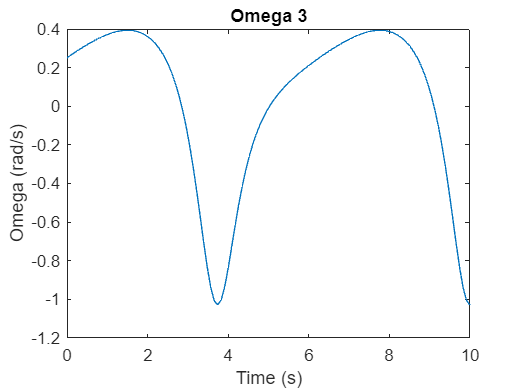

close all

plot(t,omega3)
title('Omega 3')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

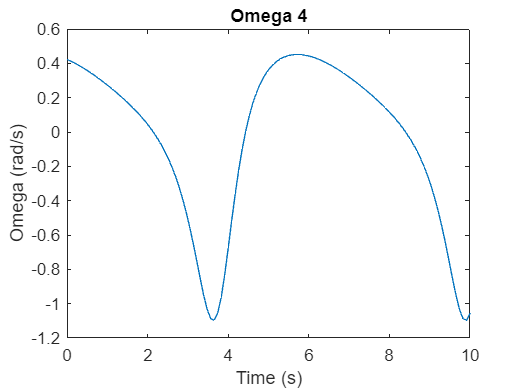


plot(t,omega4)
title('Omega 4')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

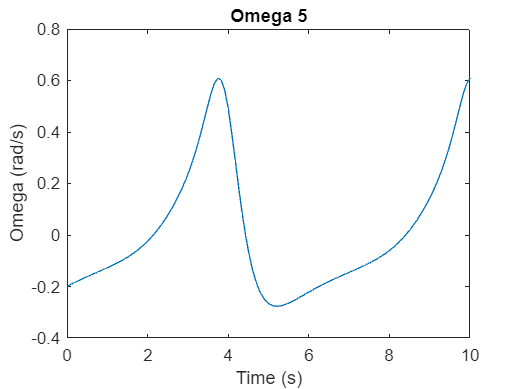


plot(t,omega5)
title('Omega 5')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

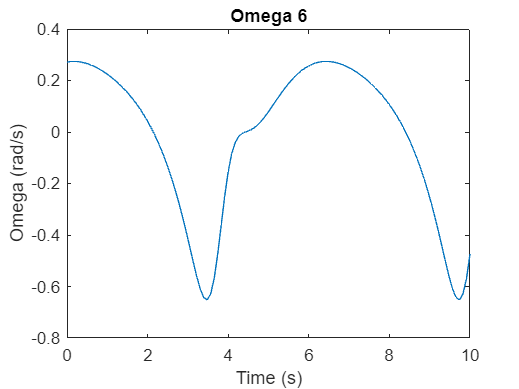


plot(t,omega6)
title('Omega 6')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

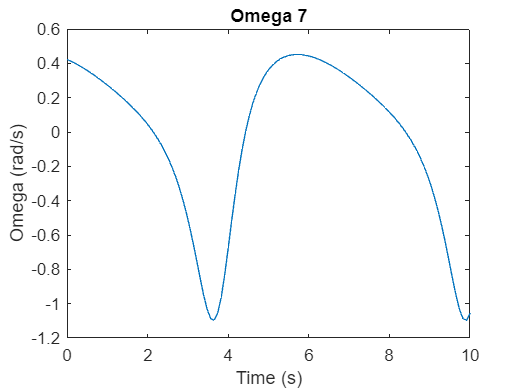


plot(t,omega7)
title('Omega 7')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

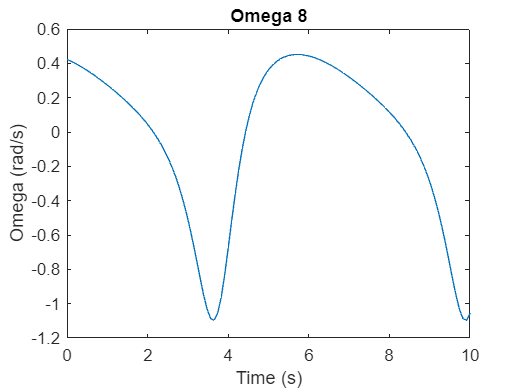


plot(t,omega8)
title('Omega 8')
xlabel('Time (s)')
ylabel('Omega (rad/s)')

## Acceleration Analysis

[alpha3 alpha4 alpha5 alpha6 alpha7 alpha8]=deal(zeros(1,116))

alpha3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


alpha4 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


alpha5 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


alpha6 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


alpha7 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


alpha8 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


k = 1;

for j = 0 : 1 : n-1

    % loop 1
   
    eq(1) = real( (-(omega_2)^2)*(exp(1i*(theta2(1,k))))*r_2 + ...
        (1i*alpha_3-(omega3(k))^2)*(exp(1i*(theta3(k))))*r_3 + ...
        (1i*alpha_4-(omega4(k))^2)*(exp(1i*(theta4(k))))*r_4 ) == 0;
    eq(2) = imag( (-(omega_2)^2)*(exp(1i*(theta2(1,k))))*r_2 + ...
        (1i*alpha_3-(omega3(k))^2)*(exp(1i*(theta3(k))))*r_3 + ...
        (1i*alpha_4-(omega4(k))^2)*(exp(1i*(theta4(k))))*r_4 ) == 0;
   
    [sol_alpha3, sol_alpha4] = vpasolve([eq(1) eq(2)] , [alpha_3 alpha_4]);
    alpha3(k) = sol_alpha3;
    alpha4(k) = sol_alpha4;
    % loop 2

    alpha7(k) = alpha4(k);
    alpha8(k) = alpha4(k);

    % loop 3

    eq(3) = real( (1i*alpha7(k)-(omega7(k))^2)*(exp(1i*theta7(k)))*r_7...
        + (1i*alpha_5-(omega5(k))^2)*(exp(1i*theta5(k)))*r_5 ) ==...
        real( (1i*alpha_6-(omega6(k))^2)*(exp(1i*theta6(k)))*r_6 );
    eq(4) = imag( (1i*alpha7(k)-(omega7(k))^2)*(exp(1i*theta7(k)))*r_7 ...
        + (1i*alpha_5-(omega5(k))^2)*(exp(1i*theta5(k)))*r_5 ) ==...
        imag( (1i*alpha_6-(omega6(k))^2)*(exp(1i*theta6(k)))*r_6 );
   
    [sol_alpha5, sol_alpha6] = vpasolve([eq(3) eq(4)] , [alpha_5 alpha_6]);
    alpha5(k) = sol_alpha5;
    alpha6(k) = sol_alpha6;

    k = k + 1;
   
end

## Ploting Acceleration Analysis

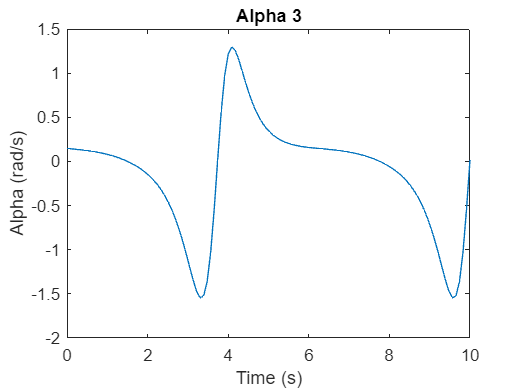

close all

plot(t,alpha3)
title('Alpha 3')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

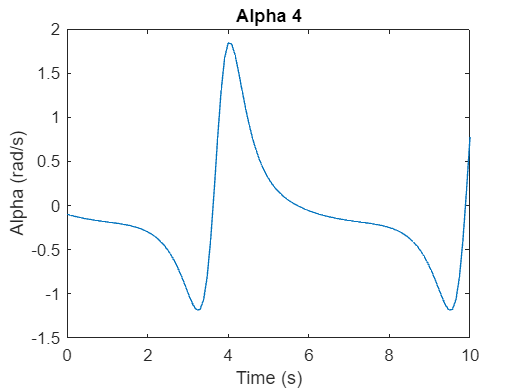


plot(t,alpha4)
title('Alpha 4')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

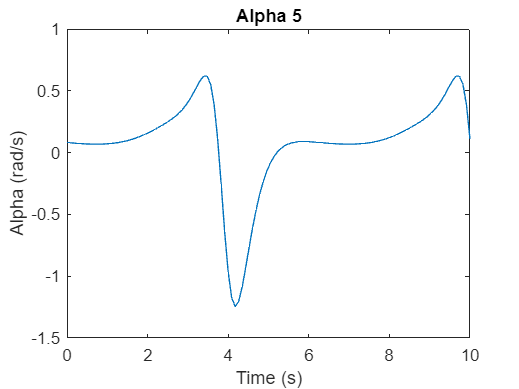


plot(t,alpha5)
title('Alpha 5')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

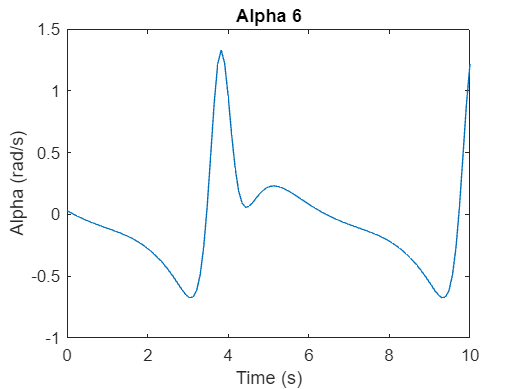


plot(t,alpha6)
title('Alpha 6')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

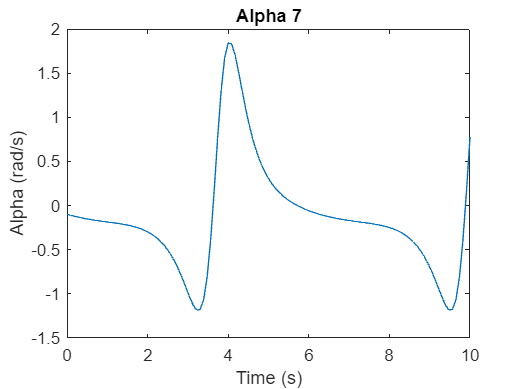


plot(t,alpha7)
title('Alpha 7')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

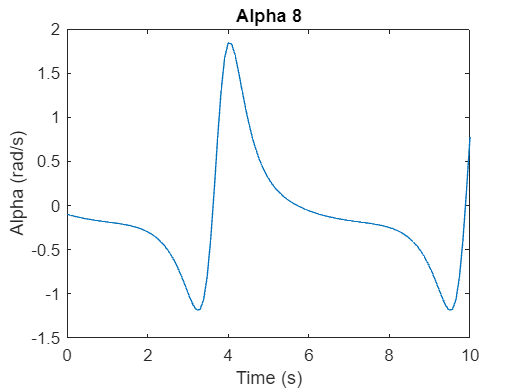


plot(t,alpha8)
title('Alpha 8')
xlabel('Time (s)')
ylabel('Alpha (rad/s)')

## Force Analysis

k = 1;
for j = 0 : 1 : n-1

    n2 = [cos(theta2(k)) ; sin(theta2(k))];
    e2 = [-sin(theta2(k)) ; cos(theta2(k))];

    n3 = [cos(theta3(k)) ; sin(theta3(k))];
    e3 = [-sin(theta3(k)) ; cos(theta3(k))];

    n4 = [cos(theta7(k)+theta_14); sin(theta7(k)+theta_14)];
    e4 = [-sin(theta7(k)+theta_14) ; cos(theta7(k)+theta_14)];

    n5 = [cos(theta5(k)) ; sin(theta5(k))];
    e5 = [-sin(theta5(k)) ; cos(theta5(k))];

    n6 = [cos(theta6(k)) ; sin(theta6(k))];
    e6 = [-sin(theta6(k)) ; cos(theta6(k))];

    n7 = [cos(theta7(k)) ; sin(theta7(k))];
    e7 = [-sin(theta7(k)) ; cos(theta7(k))];

    n54 = -[cos(theta8(k)-pi+theta_54) ; sin(theta8(k)-pi+theta_54)];
   
    n34 = -[cos(theta4(k)+theta_34) ; sin(theta4(k)+theta_34)];

    A_G_2 = -r_2/2*omega_2^2*n2;

    A_G_3 = 2*A_G_2 - r_3/2*omega3(k)^2*n3 + r_3/2*alpha3(k)*e3;

    A_G_4 = -r_14*omega4(k)^2*n4 + r_14*alpha4(k)*e4;

    A_G_6 = -r_6/2*omega6(k)^2*n6 + r_6/2*alpha6(k)*e6;

    A_G_5 = 2*A_G_6 - r_5/2*omega5(k)^2*n5 + r_5/2*alpha5(k)*e5;

    % link 2

    eq(1) = m_2*A_G_2(1) == F_12(1) + F_32(1);
    eq(2) = m_2*A_G_2(2) == F_12(2) + F_32(2) - m_2*g;
    M1 = cross([r_2/2*(-n2); 0],[F_12 ; 0]) + cross([r_2/2*(n2); 0]...
        ,[F_32 ; 0]);
    eq(3) = 0 == T_1 +  + M1(3);

    % link 3

    eq(4) = m_3*A_G_3(1) == F_43(1) - F_32(1) - P;
    eq(5) = m_3*A_G_3(2) == F_43(2) - F_32(2) - m_3*g;
    M2 = cross([r_3/2*(-n3); 0],[-F_32 ; 0]) + cross([r_3/2*(n3);0]...
        ,[F_43 ; 0]);
    eq(6) = I_3*alpha3(k) == M2(3);

    % link 4

    eq(7) = m_4*A_G_4(1) == F_14(1) + F_54(1) - F_43(1) ;
    eq(8) = m_4*A_G_4(2) == F_14(2) + F_54(2) - F_43(2) + P - m_4*g;
    M4 = cross([r_34*(n34); 0],[-F_43 ; 0]) + cross([r_54*(n54) ;0],...
        [F_54 ; 0])...
        + cross([r_14*(-n4) ;0],[F_14 ; 0]);
    eq(9) = I_4*alpha4(k) == M4(3);
   
    % link 5
   
    eq(10) = m_5*A_G_5(1) == F_65(1) - F_54(1);
    eq(11) = m_5*A_G_5(2) == F_65(2) - F_54(2) - m_5*g;
    M5 = cross([r_5/2*(-n5); 0],[-F_54 ; 0]) + cross([r_5/2*(n5) ;0],...
        [F_65 ; 0]);
    eq(12) = I_5*alpha5(k) == M5(3);
   
    % link 6

    eq(13) = m_6*A_G_6(1) == -F_65(1) + F_16(1) - P;
    eq(14) = m_6*A_G_6(2) == -F_65(2) + F_16(2) - m_6*g;
    M6 = cross([r_6/2*(-n6) ;0],[F_16 ; 0]) + cross([r_6/2*(n6); 0],...
        [-F_65 ; 0]);
    eq(15) = I_6*alpha6(k) == T + M6(3);

    [sol_F_12_x sol_F_12_y sol_F_32_x sol_F_32_y sol_F_43_x sol_F_43_y...
        sol_F_54_x ...
        sol_F_54_y sol_F_14_x sol_F_14_y sol_F_65_x sol_F_65_y sol_F_16_x...
        sol_F_16_y sol_T_1] =...
        vpasolve(eq , [F_12(1) F_12(2) F_32(1) F_32(2) F_43(1) F_43(2)...
        F_54(1) ...
        F_54(2) F_14(1) F_14(2) F_65(1) F_65(2) F_16(1) F_16(2) T_1]);
   
    F12x(k) = sol_F_12_x;
    F12y(k) = sol_F_12_y;
    F32x(k) = sol_F_32_x;
    F32y(k) = sol_F_32_y;
    F43x(k) = sol_F_43_x;
    F43y(k) = sol_F_43_y;
    F54x(k) = sol_F_54_x;
    F54y(k) = sol_F_54_y;
    F14x(k) = sol_F_14_x;
    F14y(k) = sol_F_14_y;
    F65x(k) = sol_F_65_x;
    F65y(k) = sol_F_65_y;
    F16x(k) = sol_F_16_x;
    F16y(k) = sol_F_16_y;
    T1(k) = sol_T_1;


    k  = k + 1;

end

## Ploting Force Analysis

close all

plot(t,F12x)
title('F12x and F12y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F12y)
legend({'F12x' , 'F12y'})
hold off

plot(t,F32x)
title('F32x and F32y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F32y)
legend({'F32x' , 'F32y'})
hold off

plot(t,F43x)
title('F43x and F43y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F43y)
legend({'F43x' , 'F43y'})
hold off

plot(t,F54x)
title('F54x and F54y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F54y)
legend({'F54x' , 'F54y'})
hold off

plot(t,F14x)
title('F14x and F14y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F14y)
legend({'F14x' , 'F14y'})
hold off

plot(t,F65x)
title('F65x and F65y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F65y)
legend({'F65x' , 'F65y'})
hold off
 
plot(t,F16x)
title('F16x and F16y')
xlabel('Time (s)')
ylabel('Force (rad/s)')
hold on
plot(t,F16y)
legend({'F16x' , 'F16y'})
hold off

plot(t,T1)
title('T1')
xlabel('Time (s)')
ylabel('Force (rad/s)')